twitter_black_list = ["/?", "/i/", "/settings", "/explore", "/status", "/search", "?q", "business.twitter", "/en/",...
    "accounts.google", "appleid.apple", "about.twitter", "status.twitterstat", "/privacy", "/tos"];
twitter_white_list = ["https://twitter.com"];

wikipedia_black_list = ["/Talk:", "/User:", "/User_talk:", "/Wikipedia:", "/Wikipedia_talk:", ...
             "/File:", "/File_talk:", "/MediaWiki:", "/MediaWiki_talk:", ...
             "/Template:", "/Template_talk:", "/Help:", "/Help_talk:", ...
             "/Category:", "/Category_talk:", "/Special:", "/Portal:", ...
             "/Main_Page", "#", ".ogg", ".jpg", ".jpeg", ".png", ".gif", ...
             ".svg", ".pdf", ".djvu", ".webm", ".mp3", ".mp4", ".ogv", ".oga", "(identifier)"];
wikipedia_black_list = string(wikipedia_black_list);
wikipedia_white_list = ["en.wikipedia.org/wiki"];

reddit_black_list = ["/comments", "/?", "/wiki",...
    "/new", "/rising", "/hot", "/top", "/gilded", "/search", "/popular",...
    "/about", "/rules", "/submit", "/#", "/predictions", "/controversial",...
    "?f=flair_name", "/collection", "/faq"];
reddit_white_list = ["www.reddit.com/r"];

save_name = "pagerank_wikipedia"

save_name = "pagerank_wikipedia"

[adjacency_matrix, node_labels] = webCrawler("https://en.wikipedia.org/wiki/PageRank", 1, 1000, wikipedia_black_list, wikipedia_white_list);

[======                                            ]
Pages visited: 155
Depth: 1
Added websites: 122/1000
https://en.wikipedia.org/wiki/Amy_Langville
     <===>       
Errors:0

Errors: 

save(save_name, 'adjacency_matrix', 'node_labels')

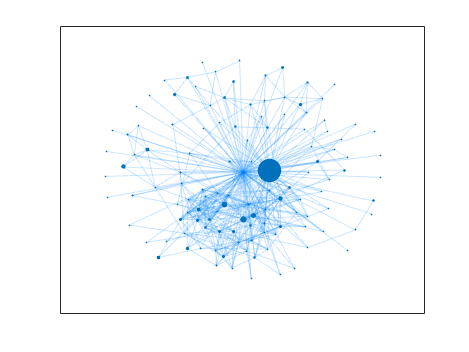


% Graph
figure;
graph = digraph(adjacency_matrix);
gp = plot(graph, 'layout', 'force','NodeLabel', {});
graph_plot = gp;
row = dataTipTextRow('label: ',node_labels);
gp.DataTipTemplate.DataTipRows(end+1) = row;
gp.EdgeColor = [0,0.5,1];
gp.EdgeAlpha = 0.2;
pr = centrality(graph, "pagerank", "FollowProbability", 0.85);
gp.MarkerSize = 20*pr/max(pr);
gp.ShowArrows = "off";